%% Global variables

% Define baseline arm geometry
rho_outer_base = 0.06;
rho_inner_base = 0.01;
rho_outer_tip = 0.03;
rho_inner_tip = 0.01;
l_0 = 0.5;
N_segments = 4;

% Define load scenario
p = [60; 0];
Q = [0; -3; 0];
Q_frame = "World";

# Taper Validation

Validating our simulation of a tapered continuum arm by recreating the following test from Oliver-Butler et al 2018

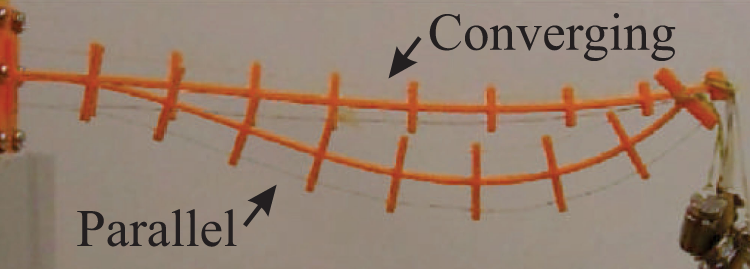

In this experiment, both arms were loaded, and then actuated to be as close to the neutral pose as possible. Note that the tapered arm ("converging" tendons) suffers less deformation under load than the un-tapered one ("parallel" tendons).

### Test 1: Un-tapered arm

constant_arm = ArmSeriesFactory.constant_2d_muscle_arm(N_segments, rho_outer_base, l_0);
constant_arm.set_mechanics(AnnealedGinaMuscleMechanics(l_0));
constant_arm.segments(1).g_0_o = Pose2.hat([0; 0; 0]);

p = [0; 100];
constant_arm.solve_equilibrium_gina(p, Q, "frame", Q_frame);

fzero residual is nonzero (> 0.01). Printing: 
   -0.0229   -0.0059    0.0062    0.0037
   -0.0000   -0.0000   -0.0000   -0.0000
   -0.3366   -0.0811    0.1124    0.0800


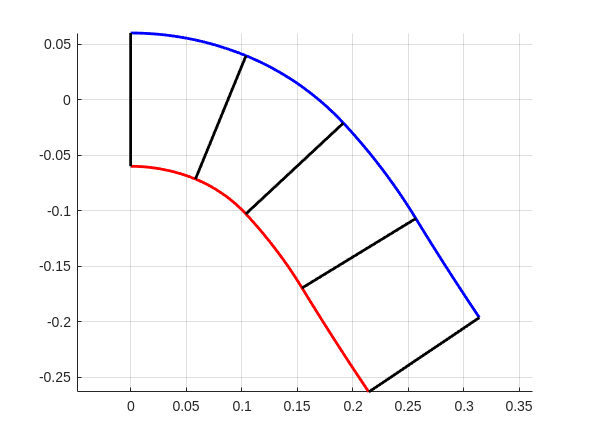

Plotter2D.plot_arm_series(constant_arm, axes(figure()));

### Test 2: Discretely-Tapered arm

tapered_arm = ArmSeriesFactory.tapered_2d_muscle_arm(N_segments, rho_outer_base, rho_outer_tip, l_0);
tapered_arm.set_mechanics(AnnealedGinaMuscleMechanics(l_0));
tapered_arm.segments(1).g_0_o = Pose2.hat([0; 0; 0]);

p = [0; 100];
g_circ_right = tapered_arm.solve_equilibrium_gina(p, Q, "frame", Q_frame);

fzero residual is nonzero (> 0.01). Printing: 
   -0.0131   -0.0027    0.0034    0.0022
   -0.0000   -0.0000   -0.0000   -0.0000
   -0.2228   -0.0502    0.0785    0.0713


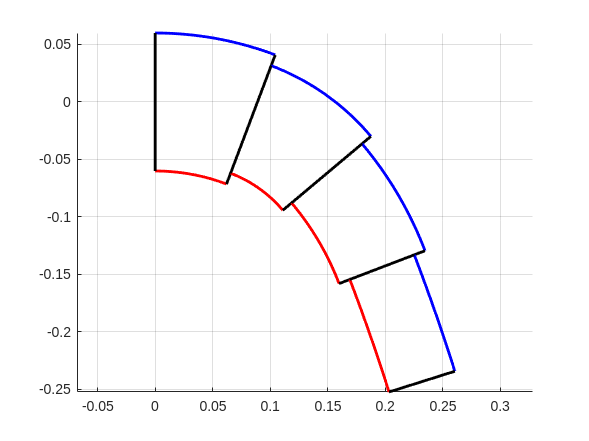

Plotter2D.plot_arm_series(tapered_arm, axes(figure()));

### Comparsion between Test 1 and 2

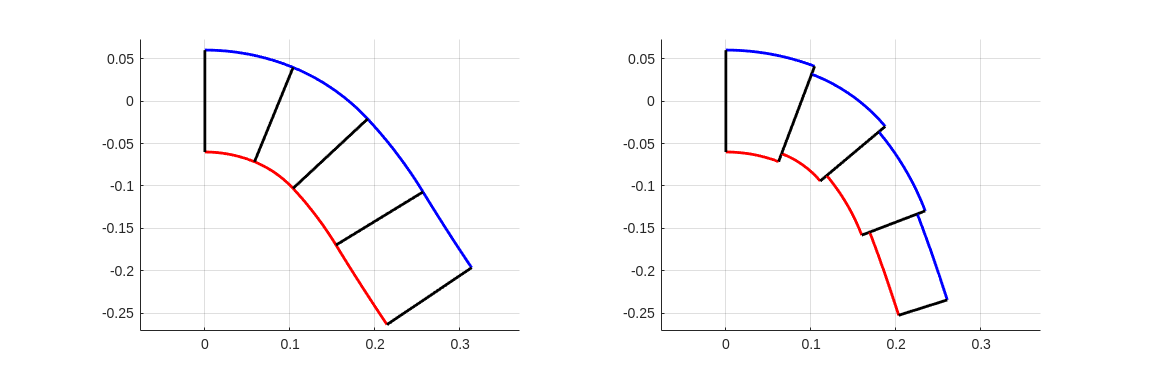

fig = figure("Position", [0, 0, 1500, 500]);
tl = tiledlayout(fig, 1, 2);
ax1 = nexttile(tl);
Plotter2D.plot_arm_series(constant_arm, ax1);

ax2 = nexttile(tl);
Plotter2D.plot_arm_series(tapered_arm, ax2);
linkaxes([ax1, ax2], "xy")

### Test 3: True-Tapered arm

% TODO: Build an arm with properly tilted muscles to validate whether the
% additional strength of the "parallel" arm comes from the changed
% orientation of the arm